# Wheels Within Wheels: MAE4730 Final Project

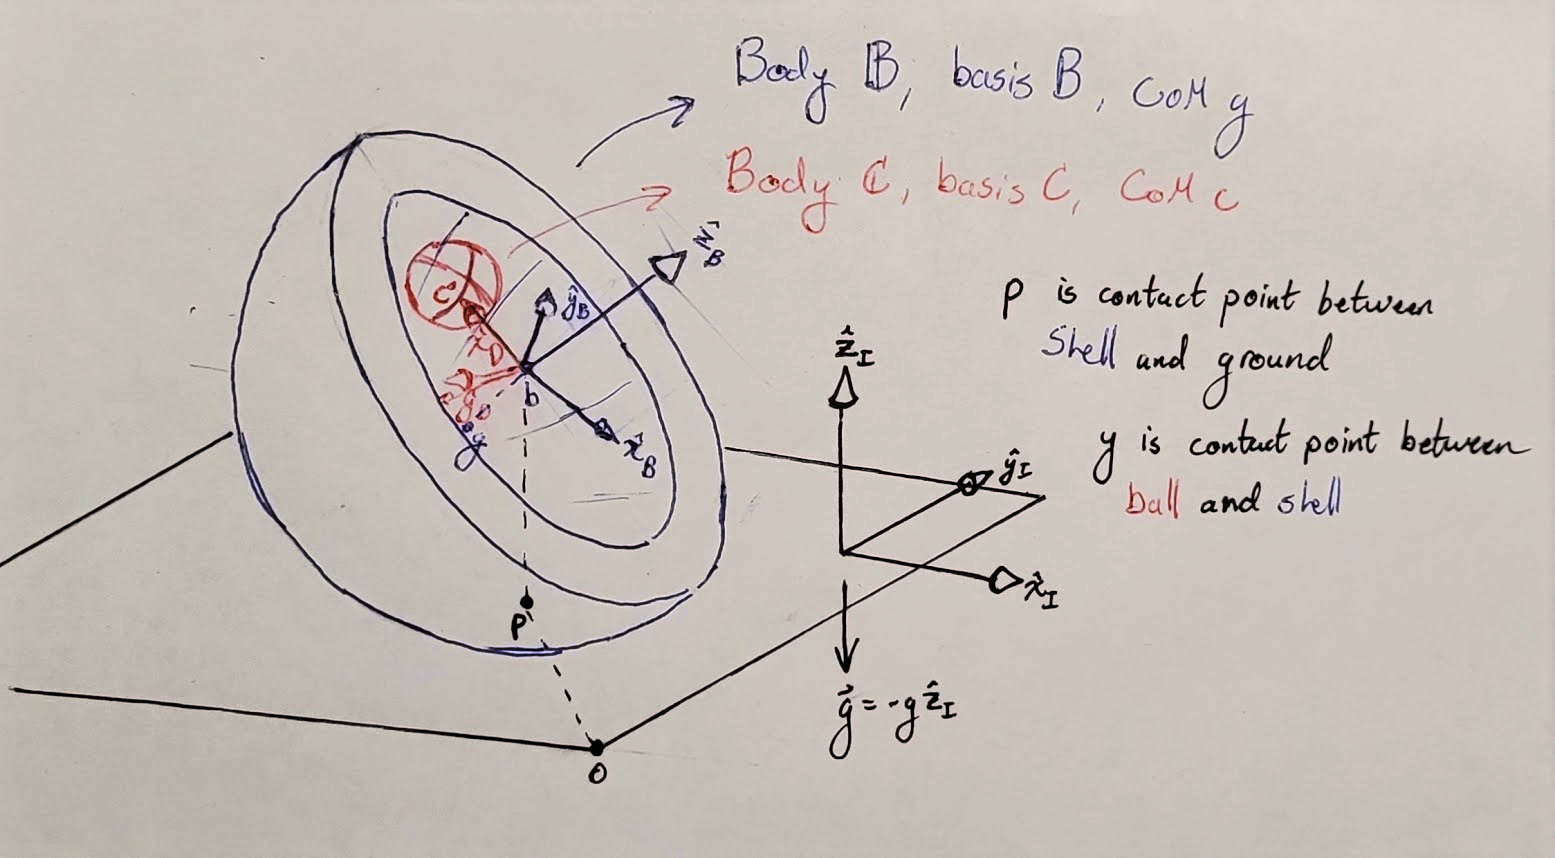

clear

% Principal parameters of shell (body B):
syms R_g R_Bo R_Bi I_p I_s m_B real positive
r_gb = [0;0;-R_g]; % basis B
I_Bg = diag([I_p,I_p,I_s]); % basis B
syms beta_x(t) beta_y(t) beta_z(t) omega_x(t) omega_y(t) omega_z(t)
% rotation matrix from inertial basis to body basis:
P_IB = spinmat([1,2,3],[beta_x,beta_y,beta_z]);
omega_BI = [omega_x;omega_y;omega_z]; % basis B
alpha_BI = diff(omega_BI,t); % basis B
% we will eventually relate the time derivatives of the euler angles to the
% angluar velocity components, but for now that is unneccessary
syms x_bo(t) y_bo(t) z_bo(t)
r_bo = [x_bo;y_bo;z_bo]; % basis I
v_bo = diff(r_bo,t);  % basis I
a_bo = diff(v_bo,t); % basis I

% Principal parameters of ball (body C):
syms R_C I_C m_C real positive
assumeAlso(R_Bi>R_C)
I_Cc = I_C*eye(3); %any basis
% Euler angles and angular velocity components:
syms gamma_x(t) gamma_y(t) gamma_z(t) Omega_x(t) Omega_y(t) Omega_z(t)
omega_CI = [Omega_x;Omega_y;Omega_z]; % basis I
alpha_CI = diff(omega_CI,t); % basis I
syms r(t) phi_z(t) phi_y(t)
r_cb = spinmat([3,2],[phi_z,phi_y])*[r;0;0];% basis I
v_cb = diff(r_cb,t); % basis I
a_cb = diff(v_cb,t); % basis I

%basis D locates the ball within the shell:
x_hat_D = spinmat([3,2],[phi_z,phi_y])*[1;0;0]; % basis I

syms g real positive

## Dynamics of body C:

%LMB:
syms F_y [3,1] real % basis I
F_c = [0;0;-m_C*g]; % basis I
F_C = F_c + F_y == m_C*(a_cb + a_bo);

% AMB:
r_yc = x_hat_D*R_C; %basis I
M_Cc = cross(r_yc,F_y) == I_Cc*alpha_CI;

## Dynamics of body B:

% LMB:
syms F_p [3,1] real % basis I
F_g = [0;0;-m_B*g]; % basis I
a_gb = cross(omega_BI,cross(omega_BI,r_gb)) + cross(alpha_BI,r_gb); % basis B
F_B = F_p + (-F_y) + F_g == m_B*(P_IB*a_gb+a_bo);

% AMB:
r_pb = [0;0;-R_Bo]; % basis I
r_pg = P_IB.'*r_pb - r_gb; % basis B
r_yb = x_hat_D*R_Bi; % basis I
r_yg = P_IB.'*r_yb - r_gb; % basis B
M_Bg = cross(r_pg,P_IB.'*F_p) + cross(r_yg,P_IB.'*(-F_y)) == I_Bg*alpha_BI  + cross(omega_BI,I_Bg*omega_BI);

## Constraints:

% no slip condition for body B rolling on ground:
v_po = cross(P_IB*omega_BI,r_pb) + v_bo == 0;
a_po = diff(v_po,t);

% no slip condition for body C rolling in body B:
v_yb = cross(omega_CI,r_yc) + v_cb == cross(P_IB*omega_BI,r_yb);
a_yb = diff(v_yb,t);

## Convert from functions to variables:

eqns = [F_B;M_Bg;F_C;M_Cc;a_po;a_yb];

clear r_bo v_bo a_bo
syms beta beta_dot omega omega_dot r_bo v_bo a_bo [3,1] real
syms gamma Omega Omega_dot q q_dot q_ddot [3,1] real
% q = [r; phiz; phiy]
eqns = subs(eqns,[diff([x_bo;y_bo;z_bo;r;phi_z;phi_y],t,t);diff([omega_x;omega_y;omega_z;Omega_x;Omega_y;Omega_z],t)], [a_bo;q_ddot;omega_dot;Omega_dot]);
eqns = subs(eqns,[diff([x_bo;y_bo;z_bo;beta_x;beta_y;beta_z;r;phi_z;phi_y],t);[omega_x;omega_y;omega_z;Omega_x;Omega_y;Omega_z]],    [v_bo;beta_dot;q_dot;omega;Omega]);
eqns = subs(eqns,      [x_bo;y_bo;z_bo;beta_x;beta_y;beta_z;r;phi_z;phi_y;gamma_x;gamma_y;gamma_z],  [r_bo;beta;q;gamma]);

[A,f] = equationsToMatrix(simplify(eqns(0)),[a_bo;omega_dot;q_ddot;Omega_dot;F_p;F_y]);
vars = [r_bo;beta; q;gamma; v_bo;omega; q_dot;Omega];

v_yb = subs(v_yb,[diff([r;phi_z;phi_y],t);[omega_x;omega_y;omega_z;Omega_x;Omega_y;Omega_z]], [q_dot;omega;Omega]);
v_yb = subs(v_yb,[r;phi_z;phi_y;beta_x;beta_y;beta_z],[q;beta]);
[r_dot, phiz_dot, phiy_dot] = solve(v_yb==0,q_dot);
q_dot = matlabFunction([r_dot;phiz_dot;phiy_dot],'Vars',{[R_Bi;R_C;q;omega;Omega;beta]});

%clear up some RAM
clearvars -except A f beta_dot vars q_dot

## Substitute in Values:

% dimensional parameters:
R_Bo = 1.0; % shell outer radius
R_Bi = 0.9; % shell inner radius
m_B = 5;   % shell mass
theta_b = (6/5)*pi; % angular extent of shell - 2*pi is a full sphere

R_C = 0.3; % ball radius
m_C = 3.0; % ball mass

g = 9.8;  % gravitiational acceleration

%initial conditions:
beta0 = [0.8;0.0;0.0]; % shell euler angles: x, y, z
omega0= [0.0;0.0;2.0]; % shell angular speeds, in body basis

q0 = [R_Bi-R_C; 1.5; 1]; % ball initial position: r phi_z phi_y 
% (phi_y=+-pi/2 corresponds to directly below or above center of ball)
Omega0 = [0;0;0]; % ball angular speeds, in inertial basis

%simulation duration:
tf = 10;

% don't adjust these:
P_IB0 = spinmat([1,2,3],beta0');
r_bo0 = [0;0;R_Bo]; % shell initial position - doesn't really matter
v_bo0 = cross(P_IB0*omega0,r_bo0); % shell initial velocity - must match no-slip constraint

gamma0 = [0;0;0]; % ball initial orientation - doesn't really matter
q_dot0 = q_dot([R_Bi;R_C;q0;omega0;Omega0;beta0]); % r_dot0; phiz_dot0; phiy_dot0 - must match no-slip constraint

R_g = (3/8)*((R_Bo^4-R_Bi^4)/(R_Bo^3-R_Bi^3))*(1+cos(theta_b/2));
I_p = m_B*((R_Bo^5-R_Bi^5)/(R_Bo^3-R_Bi^3))*(1/10)*(4+cos(theta_b/2)*(1+cos(theta_b/2))) - m_B*R_g^2;
I_s = m_B*((R_Bo^5-R_Bi^5)/(R_Bo^3-R_Bi^3))*(1/5 )*(2-cos(theta_b/2)*(1+cos(theta_b/2)));
I_C = (2/5)*m_C*R_C^2;

## Integrate:

hA = matlabFunction(subs(A),'Vars',{vars});
hf = matlabFunction(subs(f),'Vars',{[vars; beta_dot]});
% beta dot in terms of beta and omega
h3 = @(b,w)[(w(1)*cos(b(3))-w(2)*sin(b(3)))*sec(b(2));
             w(1)*sin(b(3))+w(2)*cos(b(3));
           -(w(1)*cos(b(3))-w(2)*sin(b(3)))*tan(b(2))+w(3)];
% gamma_dot in terms of gamma and Omega:
h4 = @(g,w)[(w(2)*sin(g(1))-w(3)*cos(g(1)))*tan(g(2))+w(1);
             w(2)*cos(g(1))+w(3)*sin(g(1));
           -(w(2)*sin(g(1))-w(3)*cos(g(1)))*sec(g(2))];

% z is structured as:
% r_bo   01:03
% beta   04:06
% q      07:09
% gamma  10:12
% v_bo   13:15
% omega  16:18
% q_dot  19:21
% Omega  22:24

function z_dot = EOM(~,z,hA,hf,h3,h4)
beta_dot = h3(z(04:06),z(16:18));
gamma_dot= h4(z(10:12),z(22:24));
u = hA(z)\hf([z;beta_dot]);
z_dot = [z(13:15);
         beta_dot;
         z(19:21);
         gamma_dot;
         u(1:12)];
end

[t,z] = ode45(@(t,z)EOM(t,z,hA,hf,h3,h4), linspace(0,tf,30*tf),[r_bo0;beta0; q0;gamma0; v_bo0;omega0; q_dot0;Omega0]);
z=z';
clear P_IB0 P_BD0 r_bo0 beta0 q0 gamma0 v_bo0 omega0 q_dot0 Omega0
clear hA hf h3 h4

## Animate:

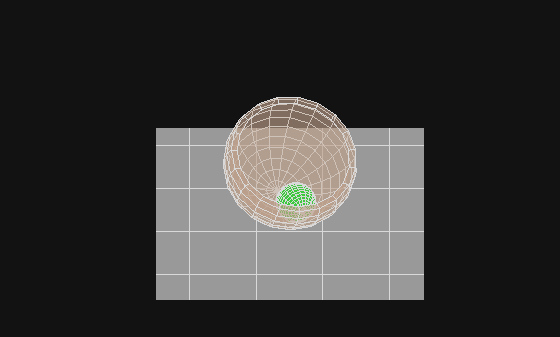

% functions to locate and orient the bodies
P_IB = @(i) spinmat([1,2,3],z([04,05,06],i)');
P_IC = @(i) spinmat([1,2,3],z([10,11,12],i)');
P_ID = @(i) spinmat([3,2],  z([08,09],i)');
r_bo = @(i) z(01:03,i);
r_co = @(i) P_ID(i)*[z(07,i);0;0] + r_bo(i);

figure(1)
clf
hold on
view([0 40])
[a,b] = meshgrid((-10:10)*R_Bo);
surf(a,b,zeros(size(a)),'FaceColor',[1,1,1]*0.6)
% make shell:
shell = hgtransform;
buildShell(shell,R_Bi,R_Bo,theta_b,[.75,.63,.54],0.4)
%make ball:
ball = hgtransform;
[a,b,c]=sphere;
surf(R_C*a,R_C*b,R_C*c,'FaceColor',[.24,.79,.24],'Parent',ball)
axis equal off
axis manual
for i = 1:length(t)
    set(shell,'Matrix',[P_IB(i),r_bo(i);[0,0,0,1]])
    set(ball ,'Matrix',[P_IC(i),r_co(i);[0,0,0,1]])
    axis([z(1,i)+[-1,1]*2*R_Bo,z(2,i)+[-1,1]*2*R_Bo,[0,1]*2*R_Bo])
    drawnow
end

## Check Conservation of Energy:

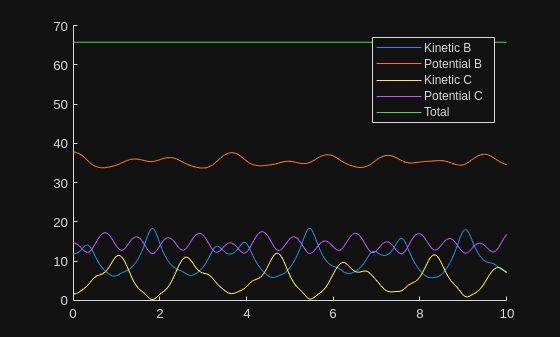

r_gb = [0;0;-R_g]; % basis B
I_Bg = diag([I_p,I_p,I_s]); % basis B
v_go = @(i) (cross(z(16:18,i),r_gb) + P_IB(i)'*z(13:15,i)); % basis B
T_B = arrayfun(@(i) (1/2)*z(16:18,i)'*I_Bg*z(16:18,i) + (1/2)*m_B*v_go(i)'*v_go(i),1:length(t));
V_B = arrayfun(@(i) [0,0,m_B*g]*(P_IB(i)*r_gb+r_bo(i)),1:length(t));

I_Cc = I_C*eye(3); %any basis
v_co = @(i) P_ID(i)*([z(19,i);0;0] + cross([-z(20,i)*sin(z(9,i));z(21,i);z(20,i)*cos(z(9,i))],[z(7,i);0;0])) + z(13:15,i);
T_C = arrayfun(@(i) (1/2)*z(22:24,i)'*I_Cc*z(22:24,i) + (1/2)*m_C*v_co(i)'*v_co(i),1:length(t));
V_C = arrayfun(@(i) [0,0,m_C*g]*r_co(i),1:length(t));

figure(2)
clf
hold on
plot(t,T_B,'DisplayName','Kinetic B')
plot(t,V_B,'DisplayName','Potential B')
plot(t,T_C,'DisplayName','Kinetic C')
plot(t,V_C,'DisplayName','Potential C')
plot(t,T_B+V_B+T_C+V_C,'DisplayName','Total')
legend

## Helper Functions:

function buildShell(hg, R_in,R_out,angle,colr,alpha)
theta = linspace(pi-angle/2,pi,round(10*angle/pi))'; phi = linspace(0,2*pi,20);
x = cos(phi).*sin(theta); y = sin(phi).*sin(theta); z = cos(theta)*ones(size(phi));
surf(R_out*x,R_out*y,R_out*z,'FaceColor',colr,'FaceAlpha',alpha,'Parent',hg)
if angle<2*pi && R_in>0
    surf(R_in*x, R_in*y, R_in*z,'FaceColor',colr,'EdgeColor','none','FaceAlpha',alpha,'Parent',hg)
    r = [R_in;R_out].*ones(size(phi));
    theta = pi-angle/2;
    x = r.*cos(phi)*sin(theta); y = r.*sin(phi)*sin(theta); z = r.*cos(theta);
    surf(x,y,z,'FaceColor',colr,'FaceAlpha',alpha,'Parent',hg)
end
end